# Test Stable manifold

## parameters


mMoon =7.348e22;% kg
mEarth = 5.9742e24; %kg
mu = mMoon/(mMoon + mEarth)

mu = 0.0122

k = 40

k = 40

## L1 stable


periodo = 3.7837

periodo = 3.7837

X0 = [0.786717447531649 0 0 0.424560784056642]

X0 =     0.7867         0         0    0.4246


STM = reshape(eye(4),16,[])';
X = [X0 STM]';
epsilon=1e-6;
%L1 stable manifold
%calculateStableMainfold(periodo,X,mu,k,100);


## L2 stable


%tFinalL2 = 4.6065
%[1.2299 0 0 -0.454910328634863]
k = 100;
periodo = 3.63716374726546

periodo = 3.6372

%X0 = [1.19878035065113	0	0	-0.308573433311396]
X0 = [1.198780 0 0 -0.308573];
C1 = jacobiConstant(X0(1,1:2),X0(1,3:4),mu)

C1 = 3.0946

STM = reshape(eye(4),16,[])';
X = [X0 STM]';

%%% plot periodic orbit
ode__opt = odeset('RelTol',1e-14,'AbsTol',1e-22);
[t, X_periodica] = ode113(@CRTBPLyapunov, [0 periodo],X , ode__opt, mu); 

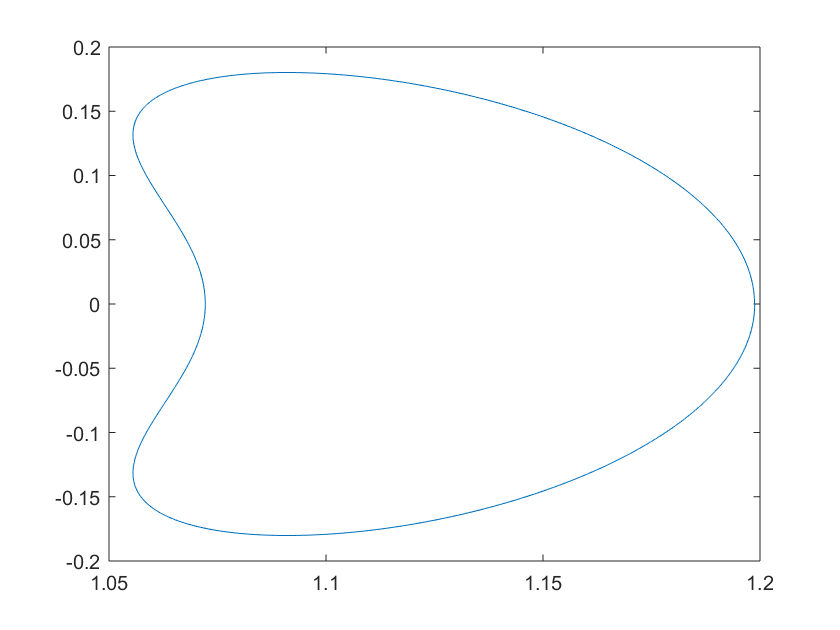

plot(X_periodica(:,1),X_periodica(:,2))

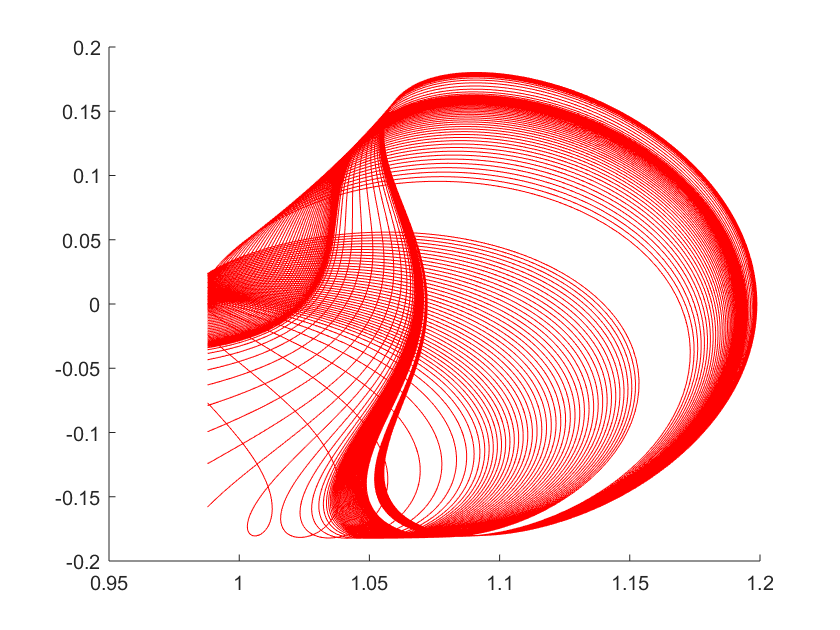

num_steps = 100

h = 1

ans =    100     4


figure

epsilon=1e-7;
%L2 stable manifold
calculateStableMainfold(periodo,X,mu,k,epsilon,1,true);